clear
clc

load('data_files/fake_signals.mat')

T = 1/Fs;
N1 = length(X1);
t = (0:N1-1)*T;
N2 = length(X2);

 %  time domain plot of X1 and X2
figure
subplot(3,2,1)
plot(t, X1, 'LineWidth', 0.5)
title('Fake signal X1 with noise')
subplot(3,2,2) 
plot(t, X2, 'LineWidth', 0.5) 
title('Fake signal X2 with noise')

m1 = ssfft(X1);  %finding one-sided amplitude spectrum of Fast Fourier Transform (FFT) using built in 'ssfft' function
m2 = ssfft(X2); 
  
% plotting the FFT graph of X1 and X2 (frequency domain)
subplot(3,2,3)
plot(m1) 
title('Spectrum of X1')
subplot(3,2,4)
plot(m2)
title('Spectrum of X2')

psd_X1 = (1/(Fs*N1)) * abs(m1).^2; % power spectral density (PSD) of X1 and X2
psd_X2 = (1/(Fs*N2)) * abs(m2).^2;

subplot(3,2,5) %plotting PSD of X1 and X2
plot(psd_X1)
title('PSD of X1')
subplot(3,2,6)
plot(psd_X2)
title('PSD of X2')

% Qusetion 9
err = abs(psd_X1 - psd_X2);  %plotting the discriminant power to identify the key diferences between X1 and X2
figure
plot(err)
title('PSD error between X1 and X2  ')

%Question 10
 hpf = high_pass(Fs);
 hpf_X1 = filter(hpf, 1, X1);
 X1_hpf = ssfft(hpf_X1);

lpf = low_pass(Fs);
lpf_X1 = filter(lpf, 1, X1);
X1_lpf = ssfft(lpf_X1);

bp = band_pass(Fs);
bp_X1 = filter(bp, 1, X1);
X1_bp = ssfft(bp_X1);

nf = notch_filter(Fs);
nf_X1 = filter(nf, 1, X1);
X1_nf = ssfft(nf_X1);

%Part 2
close all; clear all;
x = fileparts( which('sopen') );
rmpath(x);
addpath(x,'-begin');

[S HDR] = sload('data_files/c30o30_s7_t1.bdf');

Hint: the performance of SLOAD can be improved with mexSLOAD.mex which is part of biosig4c++.
WARNING SOPEN(EDF): Automated Overflowdetection not supported for EDF and BDF data, because 
   Physical Max/Min values of EDF/BDF data are not necessarily defining the dynamic range.
   For more information see: http://dx.doi.org/10.1016/S1388-2457(99)00172-8 (A. Schloegl et al. Quality Control ... Clin. Neurophysiol. 1999, Dec; 110(12): 2165 - 2170).
   A copy is available here, too: http://pub.ist.ac.at/~schloegl/publications/neurophys1999_2165.pdf 
 See also EEG2HIST: it's a tool to identify the saturation thresholds.
Warning SOPEN(BDF): File data_files/c30o30_s7_t1.bdf does not contain Status Channel - overflowdetection not supported!


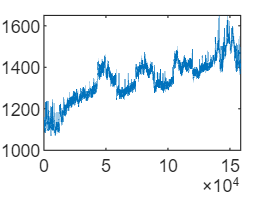

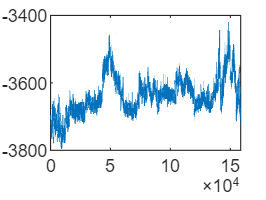

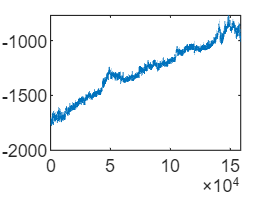

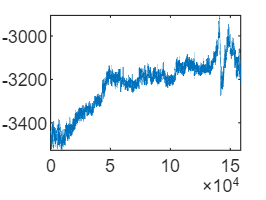

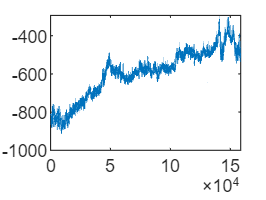

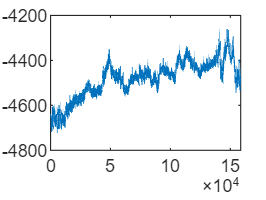

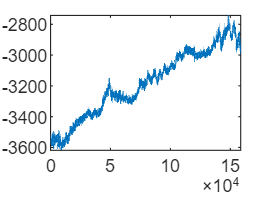

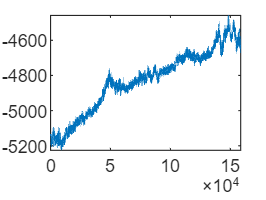


for i=1:17
figure
plot(S(:,i))
end

Fs = 512;
% Implements supplementary_code/part_2/extract_epochs.m
% Find length of signal
L = length(S);
% Differentiate trigger channel
delta_trig = S(2:L,17) - S(1:L-1,17);
% Look for rising edges
trig = find(delta_trig>0);
% Debounce if required
% I.e. remove spurious short triggers, if any
% these can occur when using a manual switch-based trigger
% e.g. look at the trigger channel in 'data_files/c30o30_s4_t1.bdf'
T_debounce = 0.5; % (in seconds) - set as desired
dt_trig = trig(2:end) - trig(1:end-1);
delete_short_trigs = find(dt_trig < Fs*T_debounce) + 1;
trig(delete_short_trigs) = [];
% How many triggers were extracted in total, after debouncing?
N_trigs = length(trig)-1;
% Ensure we have an odd number of triggers (ignore final incomplete
% epoch if not).
% Trigger 1 = start of experiment
% Triggers 2, 4, 6, 8... (2k) = eyes closed
% Triggers 3, 5, 7, 9... (2k+1) = eyes open
if mod(N_trigs, 2) == 0
 N_trigs = N_trigs - 1;
end
disp(cell2mat(strcat({'Found '}, int2str(N_trigs), {' triggers.'})));

Found 9 triggers.


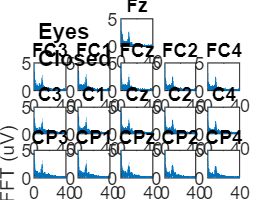


N_epochs = N_trigs;
% Discard 2 seconds of data before & after each cue
discard = 2*Fs;
% Extract each epoch of data and store in the relevant structure for
% each class
% - eyes_closed (even triggers)
% - eyes_open (odd triggers)
for i=1:N_epochs/2
 eyes_closed{i} = S(trig(2*i)+discard:trig(2*i+1)-discard,1:16);
 eyes_open{i} = S(trig(2*i+1)+discard:trig(2*i+2)-discard,1:16);
end

eyesclosedfft = ssfft(eyes_closed{2});

montage = [-1 -1 1 -1 -1; 2 3 4 5 6; 7 8 9 10 11; 12 13 14 15 16];

electrode_labels = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4','C3', 'C1',... 
                       'Cz', 'C2', 'C4','CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
% Create a new figure (or select an exisiting one if you prefer)
figure

% Iterate through each row (j) and column(i) of the montage matrix that
% will form your subplot figure
for j=1:4
    for i=1:5
        % Only create plots for electrodes that exist (ignore -1 values)
        if montage(j, i) > 0
            % which electrode is at this location in the montage matrix?
            electrode = montage(j, i);
            % select the correct (row, colum) --> what does the number 5 do
            % here?
            subplot(4, 5, i+(5*(j-1)))
            
            % plot something for the current electrode. You can plot
            % whatever data you want here, but for example:
            plotFFT2(eyesclosedfft(:,electrode), Fs)
            
            % Set axes limits if necessary, e.g.
            ylim([0 5])
            xlim([0 40])
            
            % Label each subplot with the corresponding electrode poistion
            title(electrode_labels{electrode})
            
            % Label the axes for the bottom left plot only (to prevent the
            % figure getting too crowded and illegible)
            if i == 1 && j == 4
                xlabel('Frequency (Hz)');
                ylabel('FFT (uV)')
            end
        end
    end
end

% Add a title to the entire plot - play around, as required
annotation('textbox', [0.1,0.75, 0.2, 0.2], 'String', 'Eyes Closed',...
                                'FontWeight', 'bold', 'LineStyle', 'none')

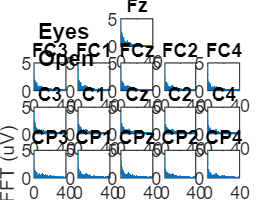


eyesopenfft = ssfft(eyes_open{2});

montage = [-1 -1 1 -1 -1; 2 3 4 5 6; 7 8 9 10 11; 12 13 14 15 16];

electrode_labels = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4','C3', 'C1',... 
                       'Cz', 'C2', 'C4','CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
% Create a new figure (or select an exisiting one if you prefer)
figure(2)

% Iterate through each row (j) and column(i) of the montage matrix that
% will form your subplot figure
for j=1:4
    for i=1:5
        % Only create plots for electrodes that exist (ignore -1 values)
        if montage(j, i) > 0
            % which electrode is at this location in the montage matrix?
            electrode = montage(j, i);
            % select the correct (row, colum) --> what does the number 5 do
            % here?
            subplot(4, 5, i+(5*(j-1)))
            
            % plot something for the current electrode. You can plot
            % whatever data you want here, but for example:
            plotFFT2(eyesopenfft(:,electrode), Fs)
            
            % Set axes limits if necessary, e.g.
            ylim([0 5])
            xlim([0 40])
            
            % Label each subplot with the corresponding electrode poistion
            title(electrode_labels{electrode})
            
            % Label the axes for the bottom left plot only (to prevent the
            % figure getting too crowded and illegible)
            if i == 1 && j == 4
                xlabel('Frequency (Hz)');
                ylabel('FFT (uV)')
            end
        end
    end
end

% Add a title to the entire plot - play around, as required
annotation('textbox', [0.1,0.75, 0.2, 0.2], 'String', 'Eyes Open',...
                                'FontWeight', 'bold', 'LineStyle', 'none')



% Implements supplementary_code/part_3/load_multiple.m


